# **Trabalho 1**

### **Ettore Padula Dalben - 20.00387-0**

## **Introdução**


$$c_n =\frac{\int_{\textrm{To}} g\left(t\right)\cdot g_n \left(t\right)\textrm{dt}}{\int_{\textrm{To}} g_n {\left(t\right)}^2 \textrm{dt}}$$


## Item 1


$$g\left(t\right)=e^{-t}$$


## Item 2


$$g_n \left(t\right)=e^{-j\cdot \omega_o \cdot n\cdot t}$$


% atribuição do imaginário j
j = 1i;

## Questão 3

% declaração de Variáveis
syms t wo to To n

% declaração de Funções
g = @(t) exp(-t);
gn = @(t,n,wo) exp(-t*j*n*wo);

% calculos simbolicos
c1 = cn(g(t), gn(t,n,wo));

% determinação das variáveis simbolicas
to = 0;
To = 1;
wo = 2*pi/To + 0i;
temp = 0:0.1:1;

%calculo do p inicial
p0 = aprox(c1, gn(t,n,wo), 0, 0);       %definição da cte. p0 em formato numérico

% reatribuição das variáveis

% calculos simples e validação de funções

%p1 = p0 + DnNum(2)*gn(t,n(1),wo) + DnNum(1)*gn(t,n(2),wo);
p1 = aprox(c1, gn(t,n,wo), p0, [1 -1]);
r1 = resto(g(t), p1);
r = subs(sum(eval(r1)),t,temp);
p = subs(p1,t,temp);

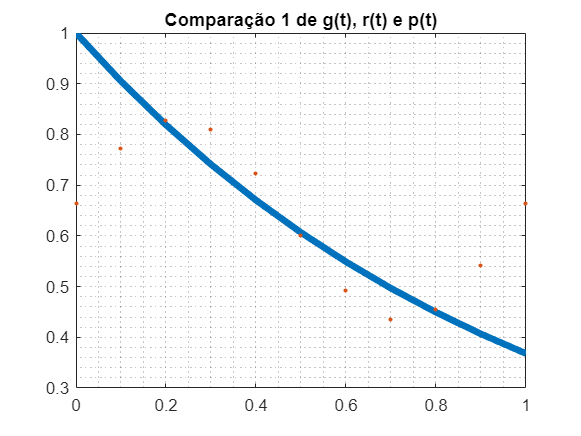

Current plot held


% exibição dos gráfcios para comparação
figure()
plot(temp,g(temp),'LineWidth',4), title('Comparação 1 de g(t), r(t) e p(t)'); grid minor
hold; scatter(temp,p,6,'filled')

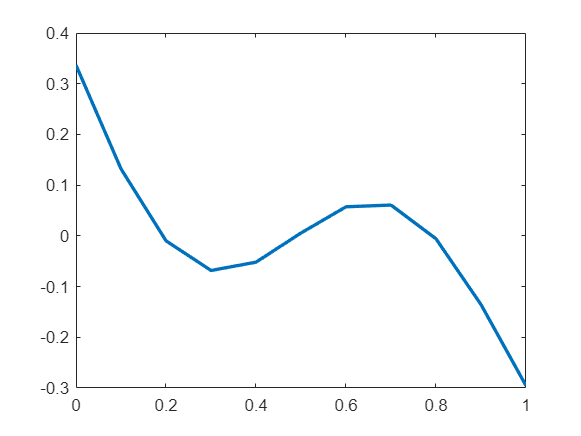

figure()
plot(temp,r,'LineWidth',2)

## Questão 4

% calculos simbolicos alternativos

%r11 = sum(eval(r11));
p10 = aprox(c1, gn(t,n,wo), 0, [1 -1]);
r10 = resto(g(t), p10);
c2 = cn(r10, gn(t,n,wo));

n = [-1i +1i];
d2 = eval(c2);
n = [+2 -2];
d1 = double(eval(c1));

% reatribuição das variáveis
syms n

Diffc = d1 - d2;
%eval(Diffc)
% comparação entre os calculos simbolicos
%Diffc = double(round(DnNum,15) -round(DnNum2,15))
disp('A diferença resultante entre os cálculos das fórmulas de c é próxima de 0, para n=2, mostrando que ambas aproximações são ortogonais');

A diferença resultante entre os cálculos das fórmulas de c é próxima de 0, para n=2, mostrando que ambas aproximações são ortogonais


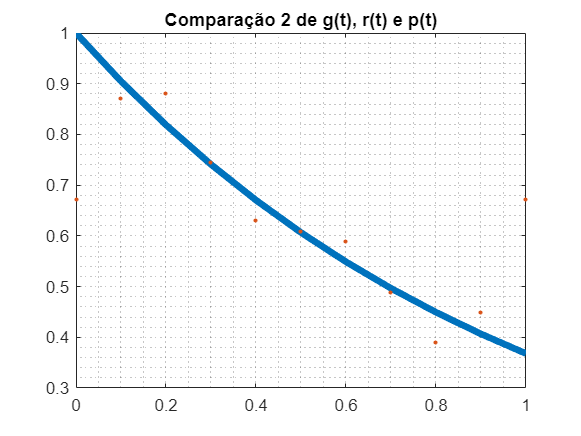

Current plot held



% calculos simples e validação de funções
p2 = aprox(c1, gn(t,n,wo), p1, [2 -2]);
r2 = resto(g(t), p2);
r = subs(r2,temp);
p = subs(p2,temp);

% exibição dos gráfcios para comparação
figure()
plot(temp,g(temp),'LineWidth',4), title('Comparação 2 de g(t), r(t) e p(t)'); grid minor
hold; scatter(temp,p,6,'filled')

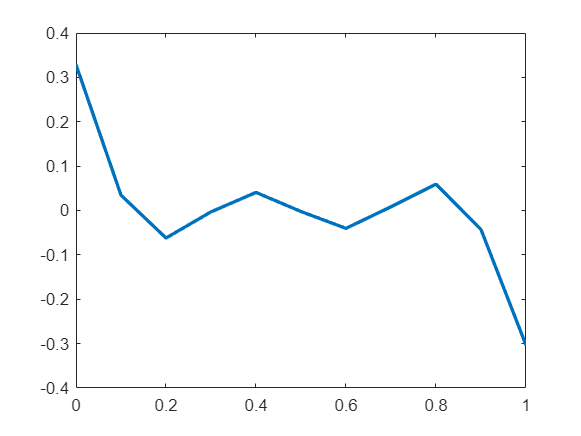

figure()
plot(temp,r,'LineWidth',2)

## Questão 5

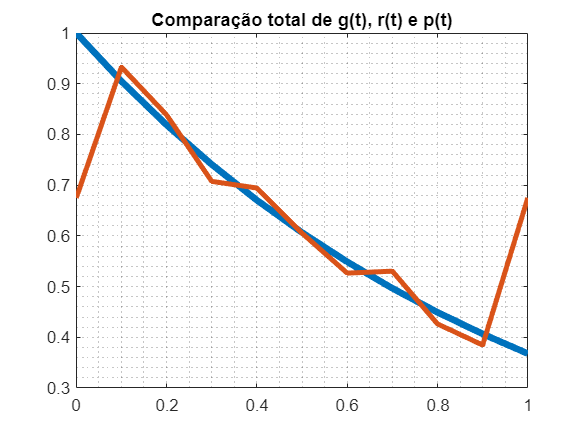

Current plot held


% calculo iterativo de toda a operação

pxa = p0;
for ite = 1:3
    px = aprox(c1, gn(t,n,wo), pxa, [ite -ite]);
    rx = resto(g(t), px);
    pxa = px;
end
r = subs(rx,temp);
p = subs(pxa,t,temp);

% exibição do gráfico final conclusivo
figure()
plot(temp,g(temp),'LineWidth',4), title('Comparação total de g(t), r(t) e p(t)'); grid minor
hold; plot(temp,p,'LineWidth',3)

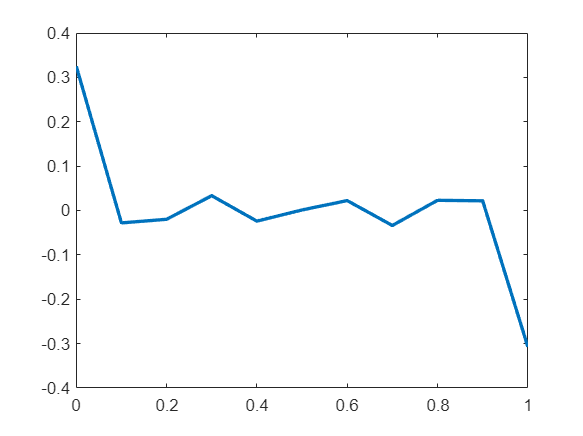

figure()
plot(temp,r,'LineWidth',2)

## 1 - Calcular a Potência

h = @(t) 1-g(t);                 %criação da função h(t) em relação a g
Pg = proj(g(t));
Ph = proj(h(t));
N = 3;
syms n

## 2 - Determinar as funções por aproximação


gm = @(t,n,wo) exp(t*j*n*wo);
cngs = 0;
for ite = 0:N
    c = cn(g(t), Pg);
    cng = apro(c, gm(t,n,wo), cngs, [-ite ite]) ;
    cngs = cng;
end

cnhs = 0;
for ite = 0:N
    c = cn(h(t), Ph);
    cnh = apro(c, gm(t,n,wo), cnhs, [-ite ite]) ;
    cnhs = cnh;
end

## 3 - Pontos do módulo de Cn

Current plot held


Current plot released


Current plot held


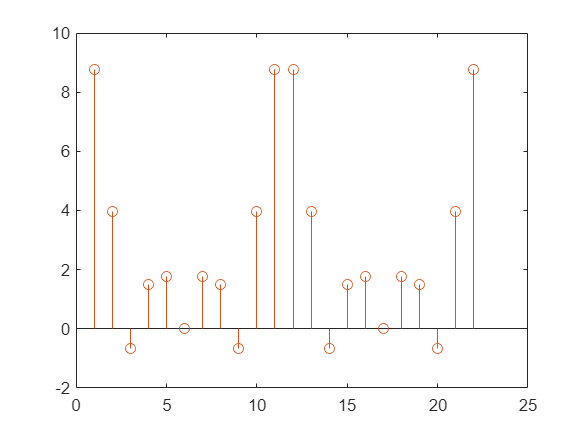

Current plot released


% ecg = eval(cngs)
syms n
for ite = 0:N
    b = eval(cnhs);
    b = subs(b,temp);
    stem(b); hold;
end

Current plot held


Current plot released


Current plot held


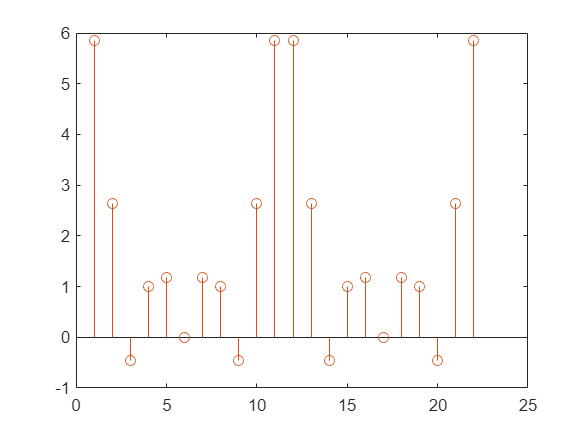

Current plot released



for ite = 0:N
    b = eval(cngs);
    b = subs(b,temp);
    stem(b); hold;
end

## 4 - Cn(g) e Cn(h)

## 5 - Como os itens anteriores se relacionam?

As funções resultam em um mesmo gráfico

function r = resto(f, p)
    syms t wo to To
    r = (f - p);
end

function p = aprox(D, f, pa, v)
    syms t wo to To
    To = 1;
    to = 0;
    wo = 2*pi/To;
    n = v;
    D = eval(D);
    f = eval(f);
    p = D*f' + pa;
end

function p = apro(D, f, pa, v)
    syms t wo to To
    To = 1;
    to = 0;
    wo = 2*pi/To;
    n = v;
    D = eval(D);
    f = eval(f);
    p = D*f + pa;
end

function c = cn(f, f2)
    syms t wo to To
    num = f * f2;
    Inum = int(num,t,to,to+To);
    den = abs(f2^2);
    Iden = int(den,t,to,to+To);
    c = (Inum/Iden);
end

function p = proj(f)
    syms t to To
    p = (1/To)*int(f^2,t,to,To);
end